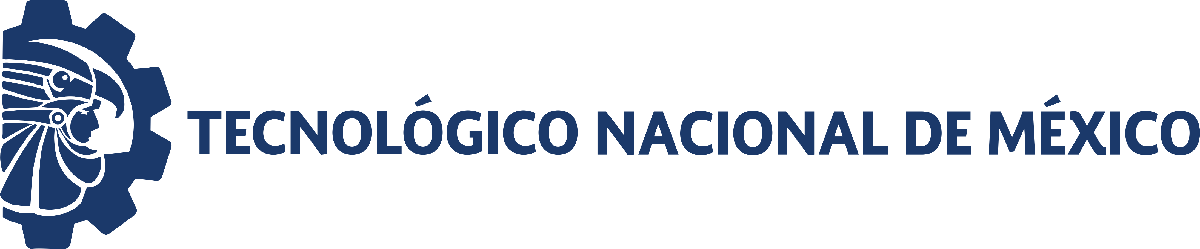                                 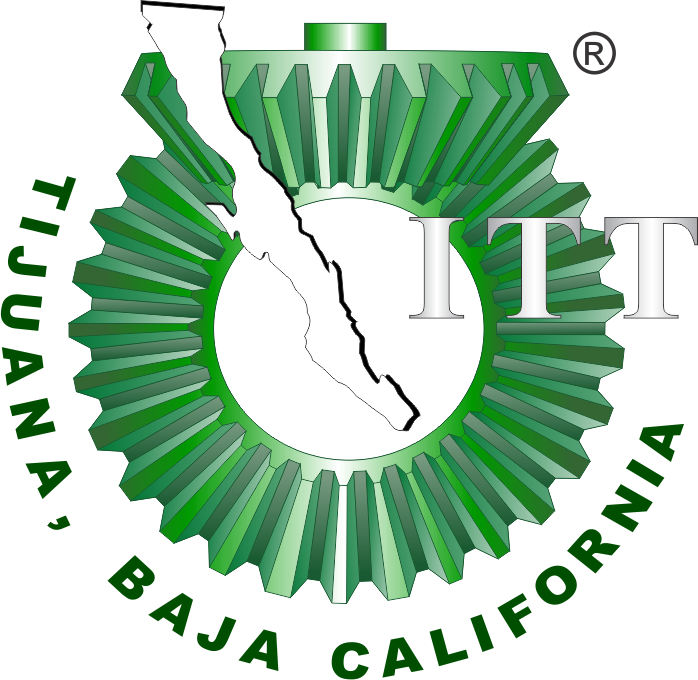

# Proyecto Final: Rinitis alergica 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumnos: -Garcia Montilla Marco Antonio - Ramirez Ruiz Jose David - Camacho Lopez Valeria - Lopez Reyes Antonio

Números de control: 22211756 -22212268 -C22211475 -22212262

Correo institucional: l22211756@tectijuana.edu.mx - l22212268@tectijuana.edu.mx - l22211475@tectijuana.edu.mx - l22212262@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

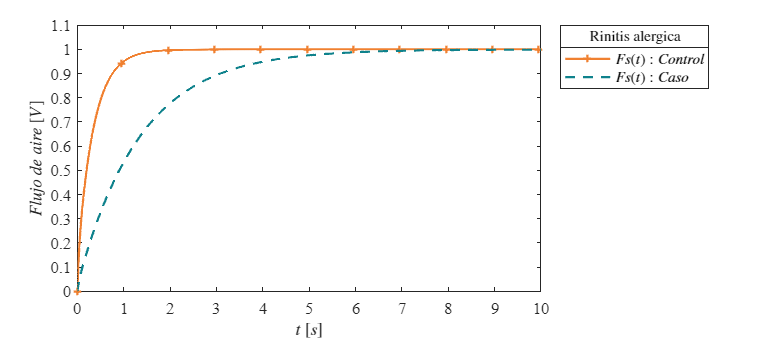

clc; clear; close all; warning('off','all')
tend = '10';
file = 'ProyectoF';
open_system(file);
parameters.StopTime=tend;
parameters.Solver = 'ode23t';
parameters.MaxStep='1E-3';
x = sim(file,parameters);
plotsignals2(x.t,x.Fs1,x.Fs2)

## Caso, control y PID

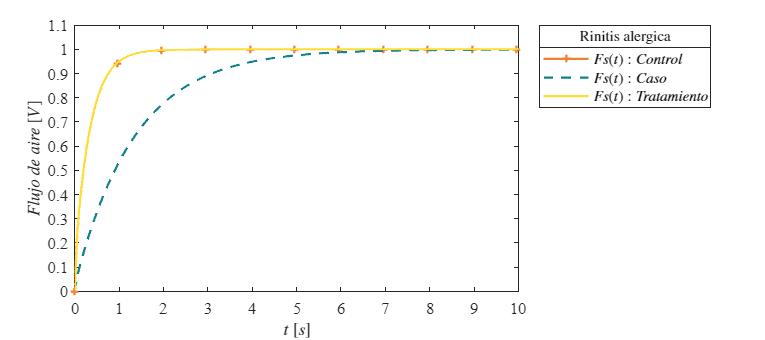

plotsignals(x.t,x.Fs1,x.Fs2,x.PID)

## Función:Respuesta a las señales

function plotsignals(t,Fs1,Fs2,PID)
    set(figure(),'Color','w')
    set(gcf,'units','centimeter','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on;grid off; box on;
    mycolors =[240,128,48;
                15,130,140;
                255,221,51;
                204,0,34;
                143,163,30;
                107,36,12]/255;
    colororder(mycolors)

    p = plot(t,Fs1,'-+',t,Fs2,'--',t,PID,'-',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',1.5);
    L = legend('$Fs(t): Control$','$Fs(t):Caso$','$Fs(t):Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,'Rinitis alergica','FontSize',10)


    xlim([0,10]); xticks(0:1:10);
    ylim([0,1.1]); yticks(-0.1:0.1:1.1);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Flujo$ $de$ $aire$ $[V]$','Interpreter','Latex','FontSize',11)
    exportgraphics(gcf,['Rinitis alergica PID','.pdf'],'ContentType','vector')
    exportgraphics(gcf,['Rinitis alergica PID','.png'],'ContentType','vector')
end

function plotsignals2(t,Fs1,Fs2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeter','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on;grid off; box on;
    mycolors =[240,128,48;
                15,130,140;
                255,221,51;
                204,0,34;
                143,163,30;
                107,36,12]/255;
    colororder(mycolors)

    p = plot(t,Fs1,'-+',t,Fs2,'--',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(2),'LineWidth',1.5);
    L = legend('$Fs(t):Control$','$Fs(t):Caso$','$Fs(t):Tratamiento(t)$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,'Rinitis alergica','FontSize',10)

    xlim([0,10]); xticks(0:1:10);
    ylim([0,1.1]); yticks(-0.1:0.1:1.1);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Flujo$ $de$ $aire$ $[V]$','Interpreter','Latex','FontSize',11)
    exportgraphics(gcf,['Rinitis alergica','.pdf'],'ContentType','vector')
    exportgraphics(gcf,['Rinitis alergica','.png'],'ContentType','vector')
end